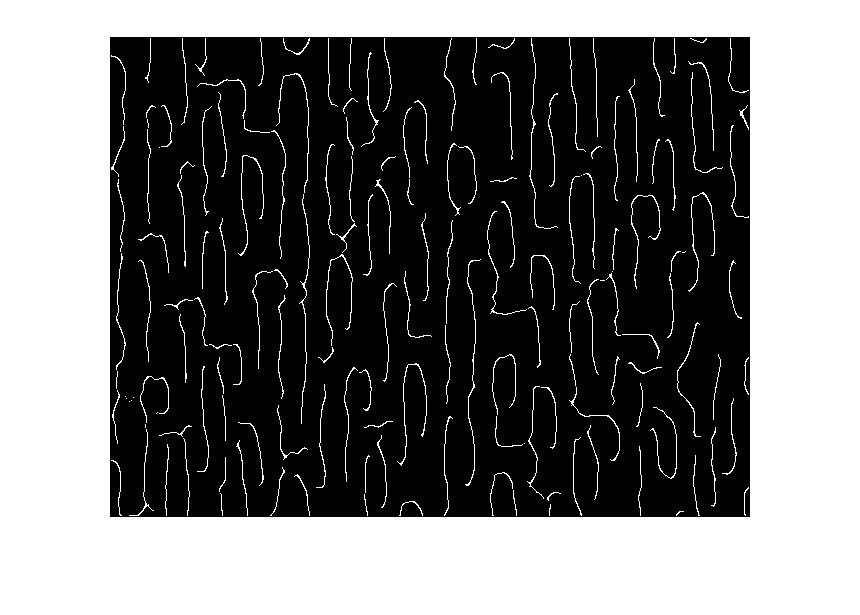

%% using canny edges and hough transformt o fiund the lines

I= imread('INTERT/1.jpg');

Igry = rgb2gray(I);

J = histeq(Igry);

%%BW = imbinarize(J);
%%BW = 1- BW;
%%SE = strel('line', 35, 90)

%%BW = imopen(BW,SE);
E= edge(J,'canny',[],10);
imshow(E);


[H,T,R] = hough(E);
peaks = houghpeaks(H,50,'Threshold',30);
lines = houghlines(E,T,R,peaks,'FillGap',5,'MinLenght',3);
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    
end

